We set up a $5\times 5$ matrix with prescribed eigenvalues, then apply the power iteration.

lambda = [1 -0.75 0.6 -0.4 0];
A = triu(ones(5),1) + diag(lambda)   % triangular matrix, eigs on diagonal

A =    1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000
                   0  -0.750000000000000   1.000000000000000   1.000000000000000   1.000000000000000
                   0                   0   0.600000000000000   1.000000000000000   1.000000000000000
                   0                   0                   0  -0.400000000000000   1.000000000000000
                   0                   0                   0                   0                   0


We run the power iteration 60 times. The best estimate of the dominant eigenvalue is the last entry of `gamma`. 

[gamma,x] = poweriter(A,60);
eigval = gamma(end)

eigval =    1.000000005357810


We check linear convergence using a log-linear plot of the error. We use our best estimate in order to compute the error at each step.

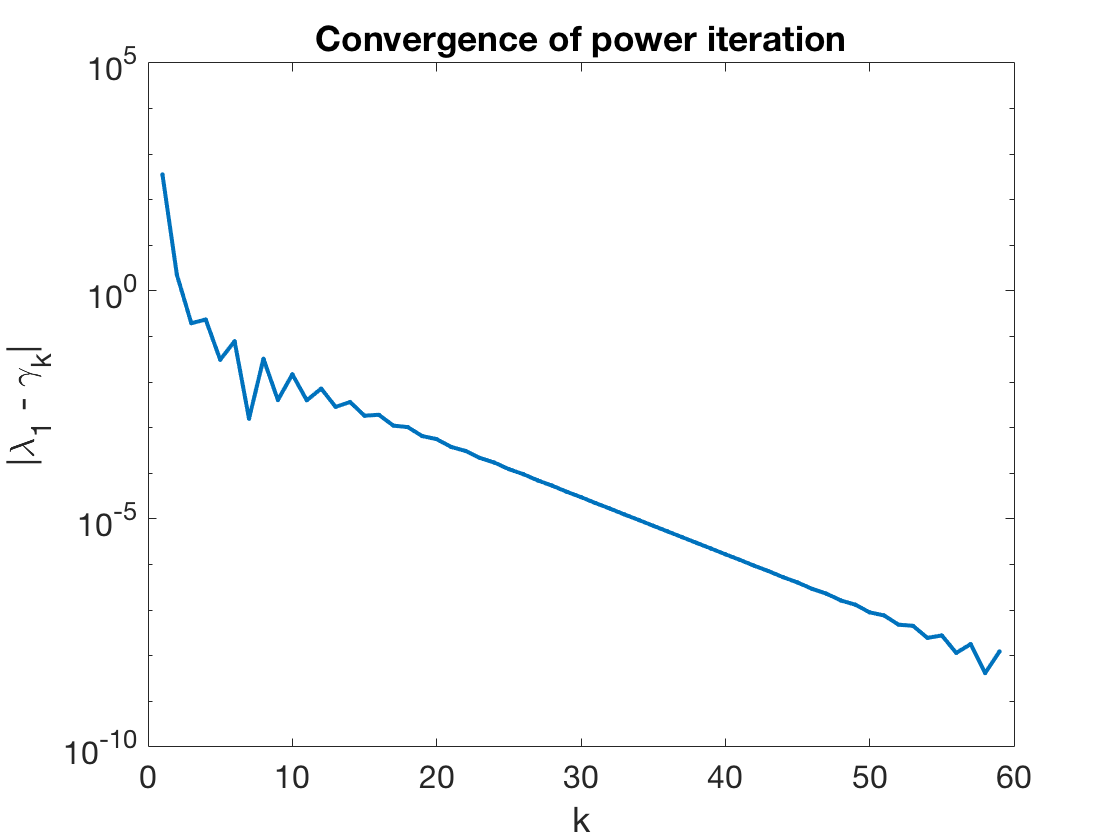

err = eigval - gamma;
semilogy(abs(err),'.-')
title('Convergence of power iteration')   % ignore this line
xlabel('k'), ylabel('|\lambda_1 - \gamma_k|')    % ignore this line

The trend is clearly a straight line asymptotically. We can get a refined estimate of the error reduction in each step by using the exact eigenvalues.

theory = lambda(2)/lambda(1)

theory =   -0.750000000000000


observed = err(40)/err(39)

observed =   -0.746985476715132


Note that the error is supposed to change sign on each iteration. An effect of these alternating signs is that estimates oscillate around the exact value.

format long
gamma(36:40)'

ans =    1.000005348494380
   0.999996000554536
   1.000003006738443
   0.999997749238344
   1.000001690646285
